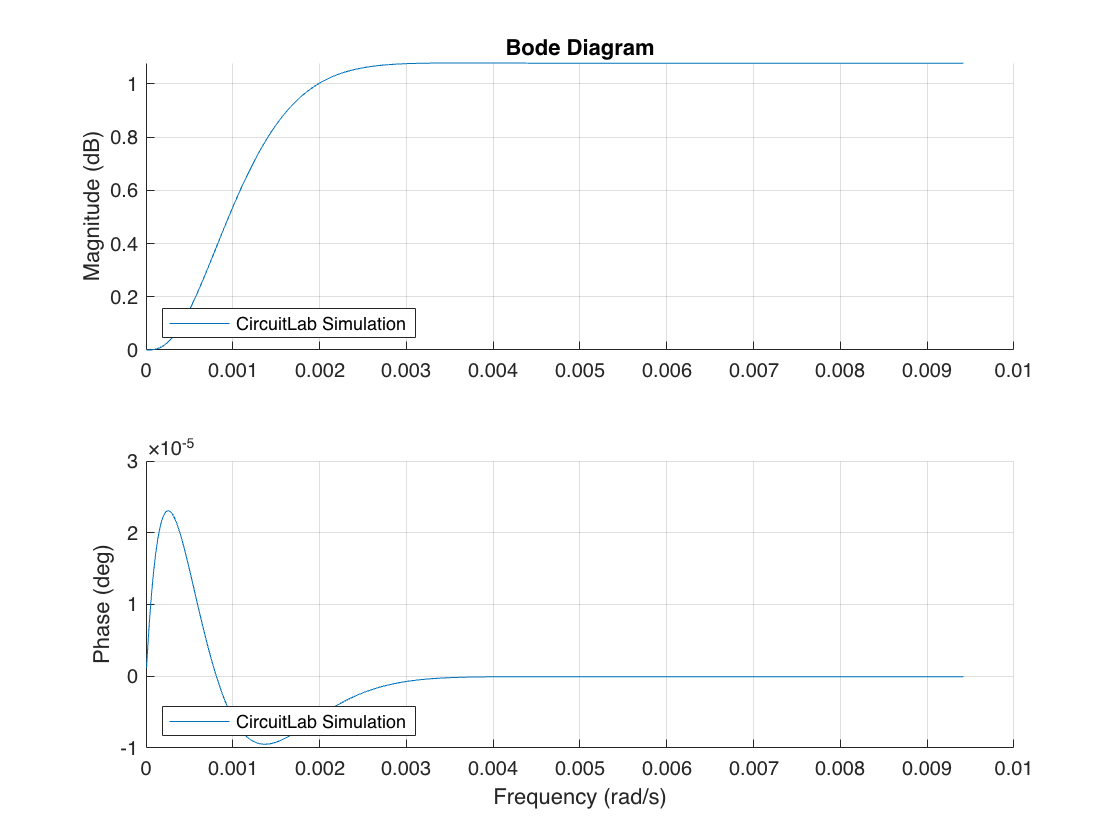

%% import CircuitLab data 
clfile='/Users/madi/Documents/GitHub/MATLAB/Final Project/Milestone 2/Time Domain.csv';
cldata=readmatrix(clfile);

%% organize circuitlab data 
clfreq=cldata(:,1);
clfreq=2.*pi.*clfreq;

clgain=cldata(:,2);

clphase=cldata(:,3);

%% plot 
subplot(2,1,1);
% semilogx(efreq,egain,'DisplayName','Measured');
hold on
semilogx(clfreq,clgain,'DisplayName','CircuitLab Simulation');
grid on
ylabel('Magnitude (dB)')
title('Bode Diagram')
legend('Location','southwest')

subplot(2,1,2);
% semilogx(efreq,ephase,'DisplayName','Measured');
hold on 
semilogx(clfreq,clphase,'DisplayName','CircuitLab Simulation');
grid on
ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')
legend('Location','southwest')
hold off 